% Лабораторная работа №11
% Кирилло Дмитрий, 2 курс, 5 группа ММФ БГУ
clear;
clc
% =============================
% Задание 1
% =============================
hold off
axis([0 10 0 10]);
hold on
mu = [2 3];
Sigma = [1 1.5; 1.5 3];
points = mvnrnd(mu,Sigma, 100);
plot(points(:,1),points(:,2),'g.','MarkerSize',10);
x = [];
y = [];
n = 1;
while n <= 2
    [x_i, y_i] = ginput(1);
    plot(x_i,y_i,'r.','MarkerSize', 10)    
    x(n) = x_i
    y(n) = y_i
    n = n+1
end

x = 1.2431

y = 7.0210

n = 2

x =     1.2431    3.1952


y =     7.0210    1.7407


n = 3

plot(x, y, 'b-');
%(y2-y1)x + (x1-x2)y + x1(y1-y2) + y1(x2-x1) = 0
%a = (x1-x2),
%b = (y2-y1),
%c = x1(y1-y2) + y1(x2-x1)
a = x(1) - x(2)

a = -1.9521

b = y(2) - y(1)

b = -5.2804

c = 20.2699

c = y(1)*(x(2) - x(1)) + x(1)*(y(1) - y(2))
disp([num2str(b) 'x + ' num2str(a) 'y + ' num2str(c) ' = 0'])

-5.2804x + -1.9521y + 20.2699 = 0


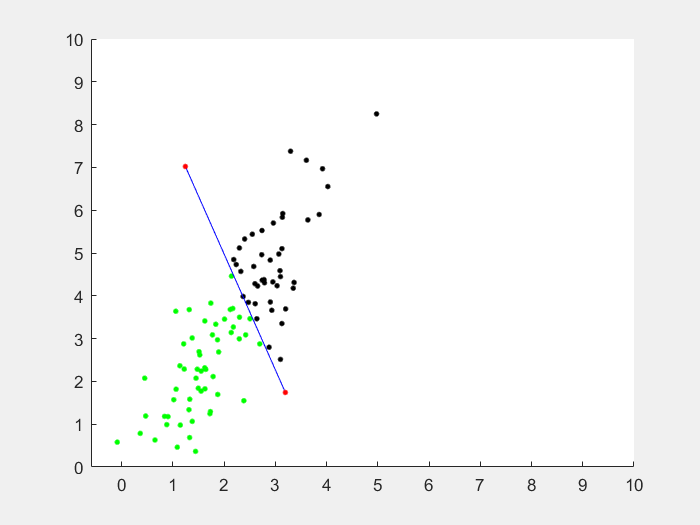

equation = @(point) point(1)*b + point(2)*a + c;
class = [];
for i = 1:length(points)
    if equation(points(i,:)) > 0
        class(i) = 1;
    else
        class(i) = 2;
    end
end
hold on;
gscatter(points(:,1), points(:,2), class,'gk','.',10, 'off');
plot(x, y, 'b-');
plot(x, y, 'r.','MarkerSize', 10);

%d
hold on;
axis([0 10 0 10]);
x = [];
y = [];
n = 1;
while n <= 2
    [x_i, y_i, button] = ginput(1);
    plot(x_i,y_i,'r.','MarkerSize', 10)    
    x(n) = x_i;
    y(n) = y_i;
    n = n+1;
end
plot(x, y, 'b-');
%(y2-y1)x + (x1-x2)y + x1(y1-y2) + y1(x2-x1) = 0
%a = (x1-x2),
%b = (y2-y1),
%c = x1(y1-y2) + y1(x2-x1)
a = x(1) - x(2)

a = -2.9466

b = y(2) - y(1)

b = 0.7477

c = y(1)*(x(2) - x(1)) + x(1)*(y(1) - y(2))

c = 20.0478

disp([num2str(b) 'x + ' num2str(a) 'y + ' num2str(c) ' = 0'])

0.74766x + -2.9466y + 20.0478 = 0


equation = @(point) point(1)*b + point(2)*a + c;
i = 1;
points = [];
class = [];
intersect = [];
while 1
    [x_i, y_i] = ginput(1);
    if equation([x_i,y_i]) > 0
        class(i) = 1;
        color = 'g.';
    else
        class(i) = 2;
        color = 'k.';
    end
    plot(x_i,y_i,color,'MarkerSize',10)
    points(i,:) = [x_i, y_i];
    if rem(i,2) ~= 1
        Xpair = [points(i,1),points(i-1,1)];
        Ypair = [points(i,2),points(i-1,2)];
        [x_i, y_i] = polyxpoly(Xpair, Ypair, x, y);
        if isempty(x_i) && isempty(y_i)
            intersect(i,:) = [NaN, NaN];
        else
            intersect(i,:) = [x_i,y_i];
        end
        plot(x_i,y_i,'b.','MarkerSize',10);
        if ~isnan(intersect(i,:))
            if class(i) == 1
                color1 = 'g-';
                color2 = 'k-';
            else
                color1 = 'k-';
                color2 = 'g-';
            end
            plot([points(i,1),intersect(i,1)],[points(i,2),intersect(i,2)],color1);
            plot([points(i-1,1),intersect(i,1)],[points(i-1,2),intersect(i,2)],color2);
        else
            if class(i) == 1
                plot(Xpair,Ypair,'g-');
            else
                plot(Xpair,Ypair,'k-');
            end
        end        
    end    
    i = i+1;
end

Error using ginput (line 82)
Interrupted by figure deletion

% =============================
% Задание 2
% =============================
hold off;
mu = [1 2 3]; Sigma = [10 4 .5; 4 5 .6; .5 .6 6];
plane = mvnrnd(mu, Sigma, 3);
points = mvnrnd(mu, Sigma, 100);
plot3(plane(:,1),plane(:,2),plane(:,3),'g.','MarkerSize',15);
hold on;
plot3(points(:,1),points(:,2),points(:,3),'r.','MarkerSize',10)
planeNormal = cross(plane(1,:) - plane(2,:),plane(1,:) - plane(3,:));
planeVector = null(planeNormal)

planeVector =     0.9338    0.3454
    0.2021   -0.2951
   -0.2951    0.8909


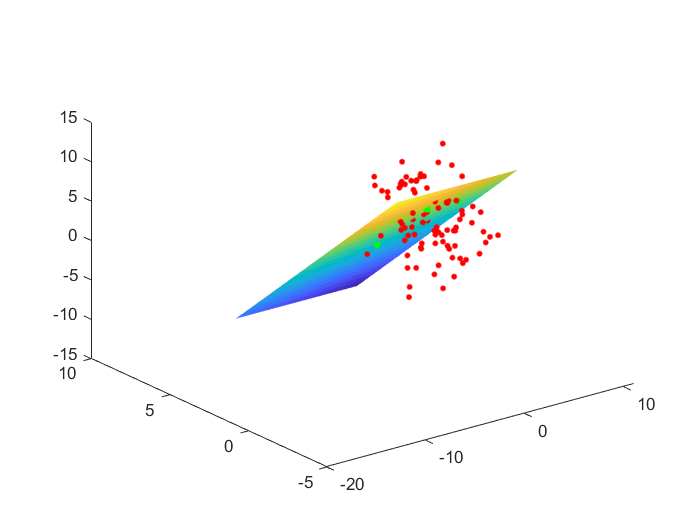

[k,t] = meshgrid(-10:10);
x = plane(1,1)+planeVector(1,1)*k+planeVector(1,2)*t; 
y = plane(1,2)+planeVector(2,1)*k+planeVector(2,2)*t;
z = plane(1,3)+planeVector(3,1)*k+planeVector(3,2)*t;
surf(x,y,z)
shading flat
equation = @(point) sum(planeNormal.*(point-plane(1,:)));
class = [];
for i = 1:100
   if equation(points(i,:)) > 0
       class(i) = 1;
   else
       class(i) = 2;
   end
end
hold off;

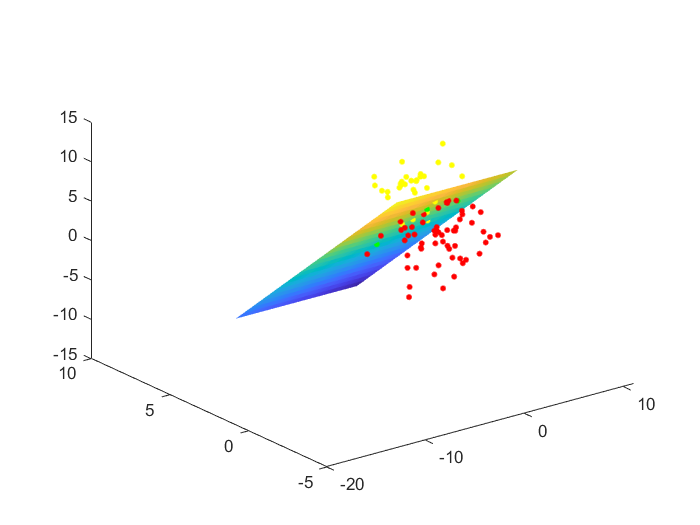

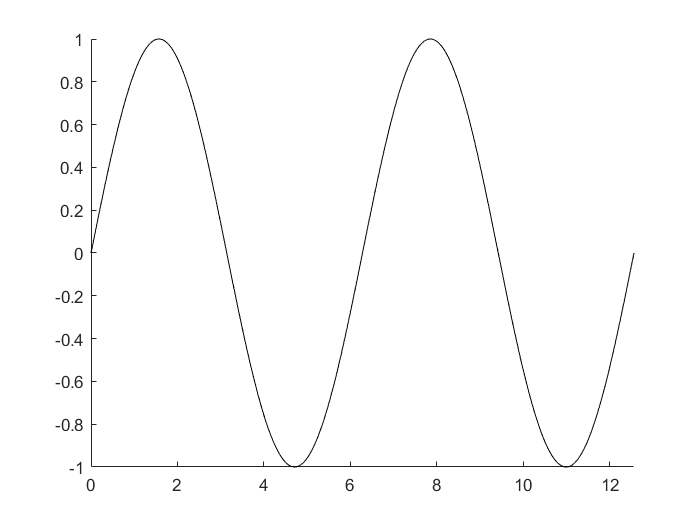

plot3(plane(:,1),plane(:,2),plane(:,3),'g.','MarkerSize',10);
hold on;
surf(x,y,z)
shading flat
group1 = points(class == 1,:);
group2 = points(class == 2,:);
plot3(group1(:,1), group1(:,2), group1(:,3), 'y.', 'MarkerSize', 10);
plot3(group2(:,1), group2(:,2), group2(:,3), 'r.', 'MarkerSize', 10);